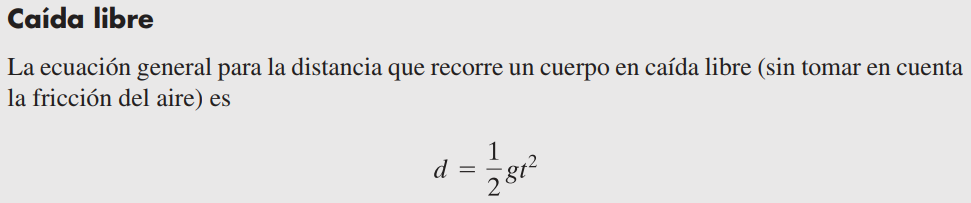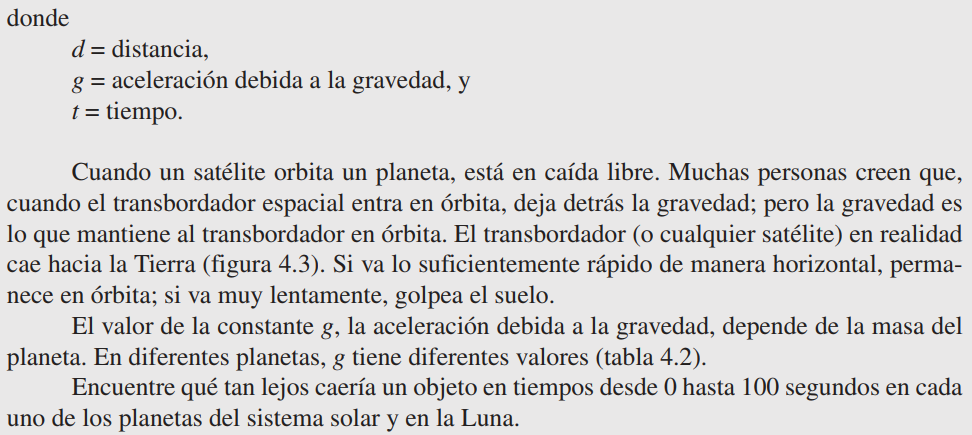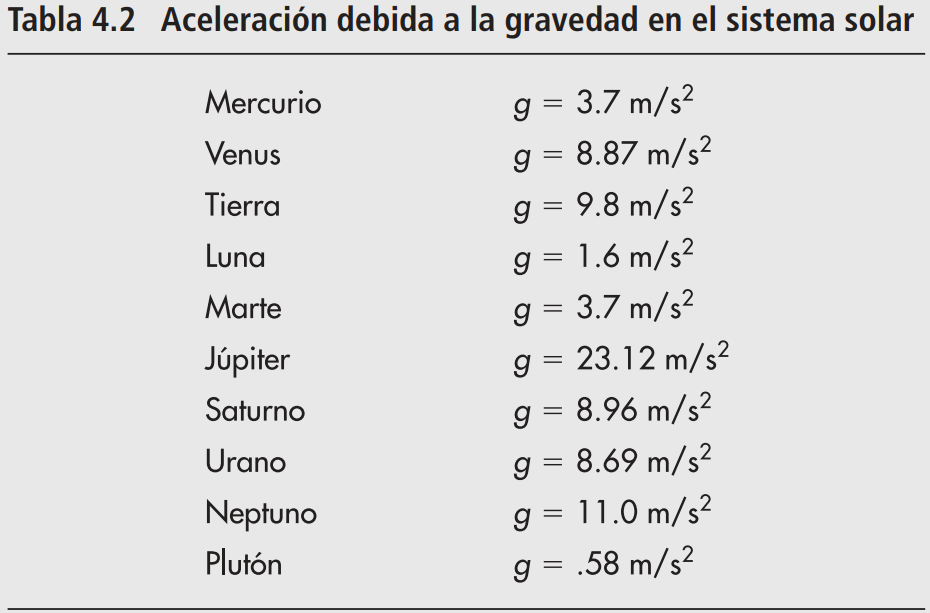

clear
format bank
% Se define lo conocido.
g = [3.7 8.87 9.8 1.6 3.7 23.12 8.96 8.69 11 .58];
t = 0:10:100;

% Se relacionan las variables.
[new_g, new_sqt] = meshgrid(g,t.^2);    % sqt es el tiempo al cuadrado.
g_sqt = [new_g .* new_sqt]';            % Gravedad en las filas, tiempo en las columnas.

% Aplicando la expresión de distancia.
planets = {'Mercurio', 'Venus','Tierra','Luna','Marte','Júpiter', ...
    'Saturno','Urano','Neptuno','Plutón'};
time_labels = {'t = 0 s' 't = 10 s' 't = 20 s' 't = 30 s' 't = 40 s' 't = 50 s' ...
    't = 60 s' 't = 70 s' 't = 80 s' 't = 90 s' 't = 100 s'};
d = array2table(.5*g_sqt,"RowNames",planets,"VariableNames",time_labels)

d = 10×11 table
                t = 0 s    t = 10 s    t = 20 s    t = 30 s    t = 40 s    t = 50 s    t = 60 s    t = 70 s    t = 80 s    t = 90 s    t = 100 s
                _______    ________    ________    ________    ________    ________    ________    ________    ________    ________    _________

    Mercurio     0.00       185.00      740.00      1665.00     2960.00     4625.00     6660.00     9065.00    11840.00    14985.00     18500.00
    Venus        0.00       443.50     1774.00      3991.50     7096.00    11087.50    15966.00    21731.50    28384.00    35923.50     4435